### **Group: Aleix Granero, Michal Szabó**

**28.10.2021**

clc; clear

# **PRACTICE 4**

## **Image Enhancement and Filtering in Spatial Domain.**

**Los píxeles que nos den una mayor diferencia son los más singulares**

**derivatives -> solbel**

**para ver las imagenes de las derivadas parciales tenemos que convertir las imagenes a grey levels para evitar los números negativos. Esto solo se hace para verlo, ya que los cálculos hay que hacerlos con la matriz con numeros negativos**

**queremos calcular una A matriz para cada pixel**

**a cada matriz A de cada píxel habría que encontrar los eigenvalues de cada matriz, pero debido a que es un proceso largo podemos usar la relación de los eigenvalues con el determinante y el trace de la matriz. con eso calcularemos un valor, y cada valor de estos será un indicador de la singularidad del píxel. Juntando todos estos píxeles creamos la matriz Mc.**

**todo esto hará que tengamos mucho ruido, así que es necesario que antes de calcular la matriz A cada matriz pase a través de un gaussian filter. cambiando el valor de sigma podremos ver como cambia la imagen final. **

### **Exercise 3.3**

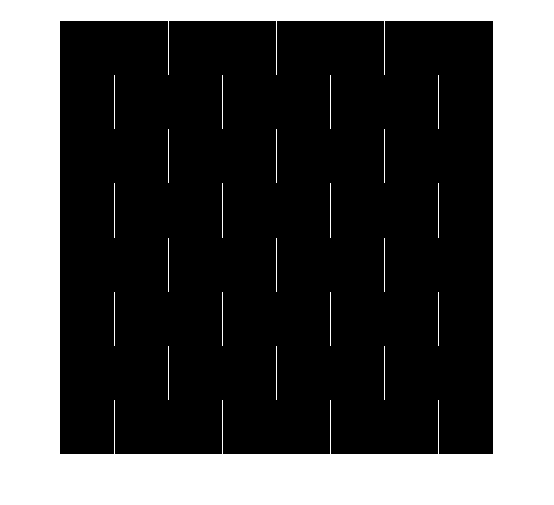

I = imread('images\chess.jpg');
I = rgb2gray(I);
sigma = 5;

sobelx = [-1 0 1; -2 0 2 ; -1 0 1 ];
sobely = [-1 -2 -1; 0 0 0 ; 1 2 1 ];

Ix = imfilter(I,sobelx);     %Calculamos el gradiente (segunda derivada parcial)
Iy = imfilter(I, sobely);

imshow(Ix)

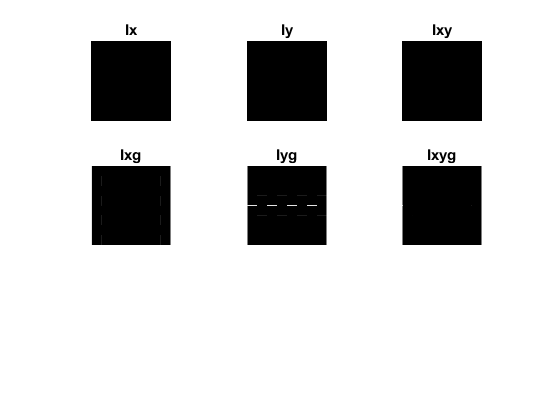


Ix2 = Ix.^2;
Iy2 = Iy.^2;
Ixy = Ix.*Iy;

% Gaussian filters
gaussian = fspecial('gaussian', sigma);
Ix2g = imfilter(Ix2, gaussian);
Iy2g = imfilter(Iy2, gaussian);
Ixyg = imfilter(Ixy, gaussian);

% Displaying results before and after gaussian filter
figure
subplot(3,3,1), imshow(Ix2), title('Ix');
subplot(3,3,2), imshow(Iy2), title('Iy');
subplot(3,3,3), imshow(Ixy), title('Ixy');
subplot(3,3,4), imshow(Ix2g), title('Ixg');
subplot(3,3,5), imshow(Iy2g), title('Iyg');
subplot(3,3,6), imshow(Ixyg), title('Ixyg');

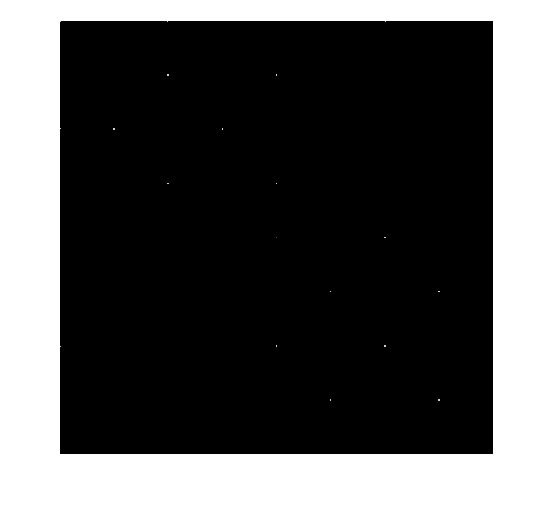


trace = Ix2g+Iy2g;
det = Ix2g.*Iy2g-Ixyg.^2;

k = 0.15;
Mc = det - k*trace.^2;
figure
imshow(Mc)